# **Constantes**

C_max  = 15;        %ml/mmHg
C_min  = 0.4;       %ml/mmHg
C_art  = 2;         % ml/mmHg
I_art  = 10^(-4);   %mmHg.s²/ml
p_LA   = 8;         %mmHg
p_RA   = 3;         %mmHg
R_hArt =  0.1;      %mmHg.s/ml
R_hCap = 1;         %mmHg.s/ml
R_AV   = 0.1;       %mmHg.s/ml
R_MV   = 10^(-2);   %mmHg.s/ml
V_r    = 5;         %ml
%C_LV = 7.5;
%C_LV = 15*sin(t) + 7.5%TODO FUNCTION
C_LV   = @(t) (7.5*sin(t) + 7.5) %TODO FUNCTION, here just approx to try ml/mmHg

C_LV = function_handle with value:
    @(t)(7.5*sin(t)+7.5)


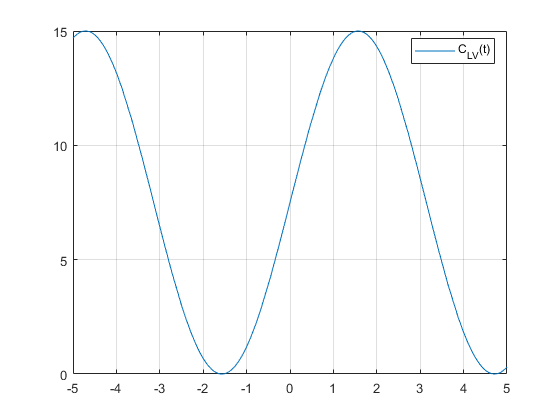



fplot(C_LV)
hold on
grid on
legend('C_{LV}(t)','Location','best')

# **Sytèmes d'équation**

syms p_LV(t) Q2(t) p1(t)

'syms' requires Symbolic Math Toolbox.


ode1 =  C_LV*diff(p_LV,t,1) == -p_LV*diff(C_LV,t,1) 
                             + ((p_LA-p_LV)/ R_MV) * heaviside(p_LA-p_LV) 
                             - ((p_LV-p1) / R_AV) * heaviside(p_LV-p1);
ode2 = I_art*diff(Q2,t,1) == p1 - p_RA - (R_hCap+R_hArt) * Q2;
ode3 = C_art*diff(p1,t,1) ==  ((p_LV-p1) / R_AV) * heaviside(p_LV-p1) - Q2;

odes = [ode1,ode2,ode3];

%TODO CONDITION LIMITE 
%cond1 = p_LV(0) == 0;
%conds = [];

[p_LVsol(t),Q2sol(t), p1sol(t)] = dsolve(odes)


# **Graphiques**


fplot(p_LVsol)
hold on
fplot(Q2sol)
fplot(p1sol)
grid on
legend('p_{LV}','Q_2','p_1','Location','best')






















